# **螺旋天线的仿真（天线工具箱仿真计算）**

**        螺旋天线具有辐射效率高、频率宽、辐射方向性好等特点。常用于卫星通信、雷达系统和移动通信等领域。MATLAB中的天线工具箱中包括螺旋天线设计模板，输入：“hx=helix; ”，则可创建螺旋天线。**

- **天线设计**

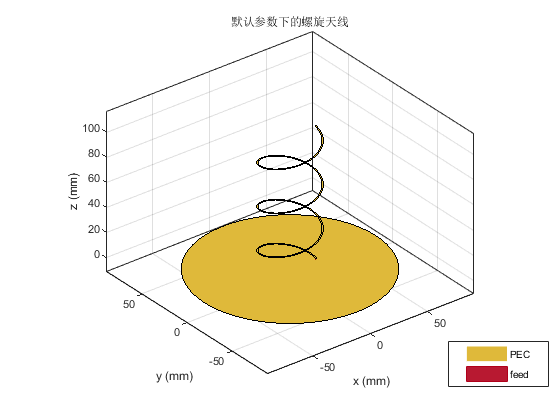

hx=helix;                                          %使用天线模型与分析库中的螺旋天线单元创建一个螺旋天线
figure                                        %显示螺旋天线hx的结构
show(hx);
title('默认参数下的螺旋天线');
set(gcf,'Visible','on');   	    %强制图片弹出显示

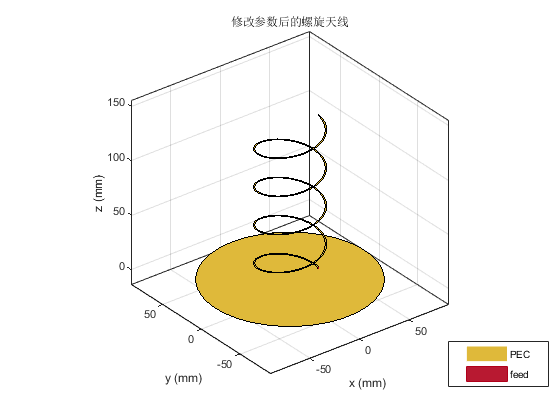

hx=helix('Radius',28e-3,'Width',1.2e-3,'Turns',4); %修正螺旋天线的参数
figure                                         %显示天线特性并观察天线结构的变化
show(hx);
title('修改参数后的螺旋天线');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真天线方向图**

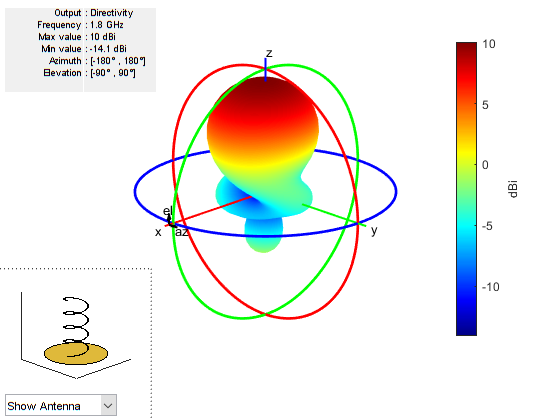

figure
pattern(hx,1.8e9);                                 %使用pattern函数绘制螺旋天线的辐射方向图

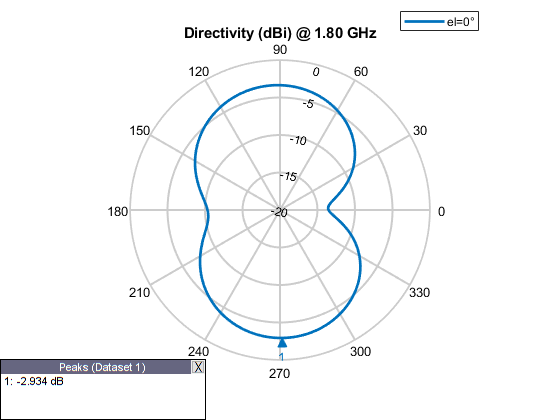

figure
patternAzimuth(hx,1.8e9);                          %绘制天线在特定工作频率下的二维方向图 

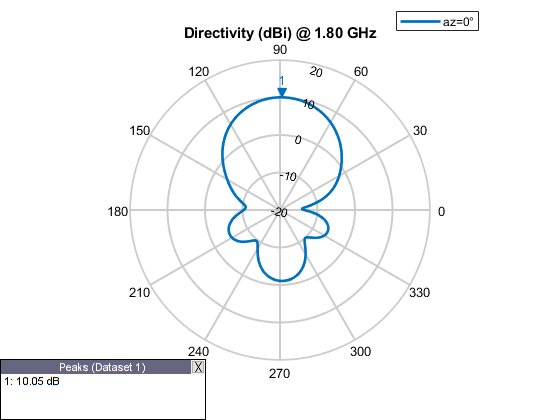

figure
patternElevation(hx,1.8e9);                        %绘制天线在特定工作频率下的二维方向图                   

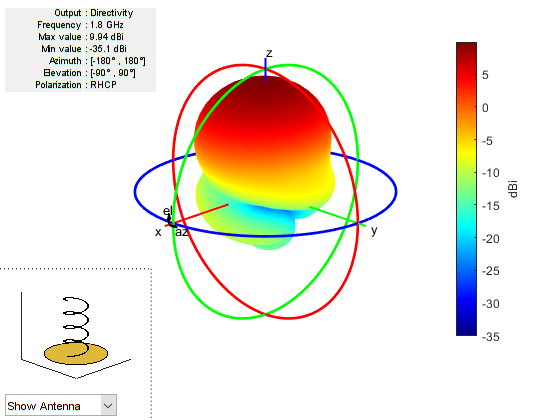

Directivity=pattern(hx,1.8e9,0,90);                %使用pattern函数还可以计算天线的方向性系数
[E,H]=EHfields(hx,1.8e9,[0;0;1]);                  %使用EHfields函数计算天线在空间一点的电场和磁场的x,y,z分量
figure
pattern(hx,1.8e9,'Polarization','RHCP');           %使用pattern函数中的极化属性绘制天线的极化方式，反射天线和接收天线应具有相同的极化方式

- **仿真计算输入阻抗**

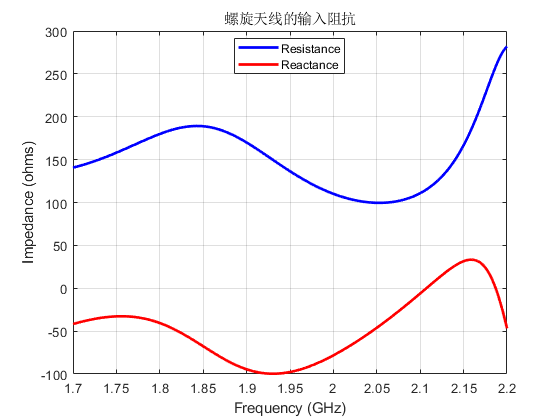

figure
impedance(hx,1.7e9:1e6:2.2e9);
title('螺旋天线的输入阻抗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算反射系数**

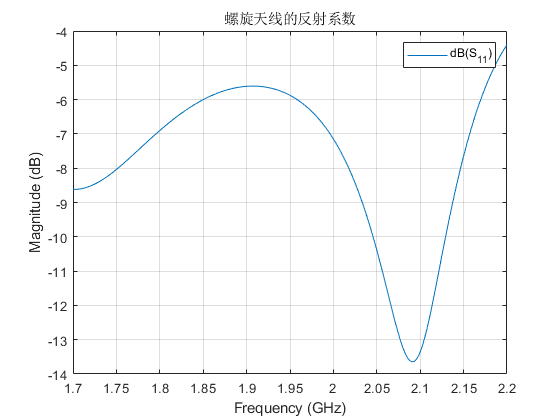

S=sparameters(hx,1.7e9:1e6:2.2e9,72);               %用sparameters函数计算天线的反射系数S11
figure
rfplot(S);
title('螺旋天线的反射系数');
set(gcf,'Visible','on');   	    %强制图片弹出显示

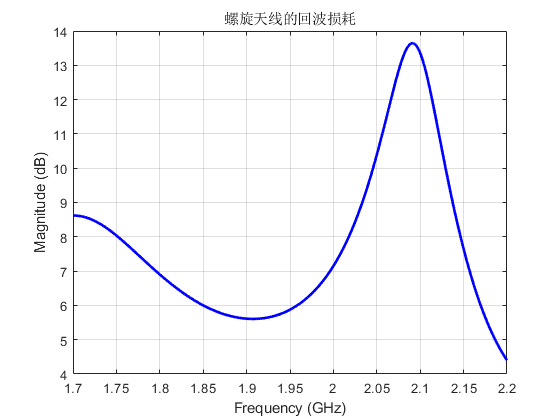

%回波损耗是反射系数绝对值的倒数，以分贝值表示，其值在0dB和无穷大之间，值越大表示匹配越好，0表示全反射，无穷大表示完全匹配
%在移动通信系统中，一般要求回波损耗大于14dB
figure
returnLoss(hx,1.7e9:1e6:2.2e9,72);                  %用returnLoss函数计算并绘制天线的回波损耗
title('螺旋天线的回波损耗');
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **仿真计算电压驻波比**

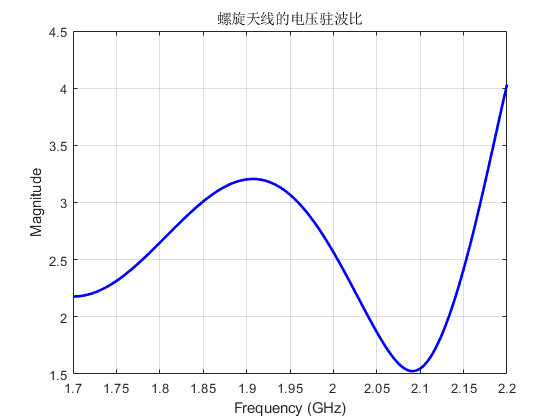

figure
vswr(hx,1.7e9:1e6:2.2e9,72);                        %用vswr函数计算并绘制天线的电压驻波比
title('螺旋天线的电压驻波比');
set(gcf,'Visible','on');   	    %强制图片弹出显示